%Generar pista de carrera
%Equipo 1
%Samuel Garcia 
%Armando Terrazas
%Isaac Ramirez
%Javier Hernandez

## **Primera Parte: encontrar valores de 'x' y 'y' plausibles en la curva**

clc
clearvars
menu=0

menu = 0

while menu ~= 7
    fprintf("\nSegmentos de Pista:\n\t1. Europa 1\n\t2. Europa 2\n\t3. Bélgica 1\n\t4. Bélgica 2\n\t5. Italia 1\n\t6. Italia 2\n\t7. Salir\n")
    menu=input("Ingresa el número correspondiente: ")
    
    if menu == 1
        % Europa
        %Europa 1
            x1 = (21/10)*25.1*(10^-3)*16583;
            y1 = (17/10)*25.1*(10^-3)*16583;
            x3 = (20/10)*25.1*(10^-3)*16583;
            y3 = (16/10)*25.1*(10^-3)*16583;
            x2 = (28/10)*25.1*(10^-3)*16583;
            y2 = (22.5/10)*25.1*(10^-3)*16583;
            x4 = (26/10)*25.1*(10^-3)*16583;
            y4 = (23/10)*25.1*(10^-3)*16583;

    elseif menu==2
            %   Europa 2
                x1 = (15/10)*25.1*(10^-3)*16583;
                y1 = (13/10)*25.1*(10^-3)*16583;
                x3 = (14/10)*25.1*(10^-3)*16583;
                y3 = (13/10)*25.1*(10^-3)*16583;
                x2 = (24/10)*25.1*(10^-3)*16583;
                y2 = (10/10)*25.1*(10^-3)*16583;
                x4 = (25/10)*25.1*(10^-3)*16583;
                y4 = (10.1/10)*25.1*(10^-3)*16583;
            
    elseif menu==3
            % Belgica
            %     Belgica 1
                x1 = (13/10)*25.1*(10^-3)*16583;
                y1 = (6.57/10)*25.1*(10^-3)*16583;
                x3 = (12/10)*25.1*(10^-3)*16583;
                y3 = (6.5/10)*25.1*(10^-3)*16583;
                x2 = (24/10)*25.1*(10^-3)*16583;
                y2 = (6/10)*25.1*(10^-3)*16583;
                x4 = (25/10)*25.1*(10^-3)*16583;
                y4 = (5/10)*25.1*(10^-3)*16583;
            
    elseif menu==4
            %     Belgica 2
                x1 = (26/10)*25.1*(10^-3)*16583;
                y1 = (10/10)*25.1*(10^-3)*16583;
                x3 = (25/10)*25.1*(10^-3)*16583;
                y3 = (10.2/10)*25.1*(10^-3)*16583;
                x2 = (31/10)*25.1*(10^-3)*16583;
                y2 = (5/10)*25.1*(10^-3)*16583;
                x4 = (32/10)*25.1*(10^-3)*16583;
                y4 = (4.5/10)*25.1*(10^-3)*16583;
            
    elseif menu==5
            % Italia
            %     Italia 1
                x1 = (2.5/10)*25.1*(10^-3)*16583;
                y1 = (5/10)*25.1*(10^-3)*16583;
                x3 = (1/10)*25.1*(10^-3)*16583;
                y3 = (6/10)*25.1*(10^-3)*16583;
                x2 = (17/10)*25.1*(10^-3)*16583;
                y2 = (0.5/10)*25.1*(10^-3)*16583;
                x4 = (18/10)*25.1*(10^-3)*16583;
                y4 = (1.2/10)*25.1*(10^-3)*16583;
            
    else 
            %     Italia 2
                x1 = (20/10)*25.1*(10^-3)*16583;
                y1 = (11/10)*25.1*(10^-3)*16583;
                x3 = (19/10)*25.1*(10^-3)*16583;
                y3 = (11/10)*25.1*(10^-3)*16583;
                x2 = (25/10)*25.1*(10^-3)*16583;
                y2 = (19/10)*25.1*(10^-3)*16583;
                x4 = (26/10)*25.1*(10^-3)*16583;
                y4 = (16/10)*25.1*(10^-3)*16583;
    end
if menu >0 && menu<7
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if x2>x1
    xmax=x2;
    xmin=x1;
    ymax=y2;
    ymin=y1;
else
    xmax=x1;
    xmin=x2;
    ymax=y1;
    ymin=y2;
end

if y2>y1
    xloc=x2;
    yloc=y2;
else
    xloc=x1;
    yloc=y1;
end

m1 = (y3-y1)/(x3-x1);
m2 = (y4-y2)/(x4-x2);

ecuacion1 = [x1^3,x1^2,x1,1; 
             x2^3,x2^2,x2,1; 
             3*x1^2,2*x1,1,0; 
             3*x2^2,2*x2,1,0];

resultados = [y1;y2;m1;m2];

m = det(ecuacion1);

ecuacionC3 = ecuacion1;
ecuacionC3(:,1) = resultados;
C3 = det(ecuacionC3)/m;

ecuacionC2 = ecuacion1;
ecuacionC2(:,2) = resultados;
C2 = det(ecuacionC2)/m;

ecuacionC1 = ecuacion1;
ecuacionC1(:,3) = resultados;
C1 = det(ecuacionC1)/m;

ecuacionC0 = ecuacion1;
ecuacionC0(:,4) = resultados;
C0 = det(ecuacionC0)/m;
plot(x1,y1,'o'); text(x1,y1,'(x_1,y_1)');
hold on
plot(x2,y2,'o'); text(x2,y2,'(x_2,y_2)');

plot([x1,x3],[y1,y3]); text(x3+0.5,y3+0.5,'dy/dx_1');
plot([x2,x4],[y2,y4]); text(x4+0.5,y4+0.5,'dy/dx_2');
xlim([xmin-(xmin/5),xmax+(xmax/5)]);
axis equal
hold off
fprintf("f(x)=%fx^3 %fx^2 %fx %f",C3,C2,C1,C0)
fprintf("f'(x)=(3 %f x^2 %f x %f) (x-x_n)+y_n",C3,C2,C1)

fprintf("P(inicial)=(%f ,%f) m   P(final)=(%f,%f) m",x1,y1,x2,y2)


## **Segunda Parte: gráfica de la función y líneas tangentes para 10 puntos**

y_p = @(x) C3*x.^3+C2*x.^2+C1*x+C0;

fprintf("Demostración que los puntos evaluados en la función son iguales:\n")
fprintf("P(inicial)=(%f ,%f) m   P(final)=(%f,%f) m\n",x1,y_p(x1),x2,y_p(x2))

dy_p = @(x) 3*C3*x.^2+2*C2*x+C1;

dy_p_2= @ (x) 6*C3*x+2*C2;

misPuntos = linspace(xmin,xmax,10);
%y = y_p(misPuntos);


fplot(y_p,[xmin,xmax],"LineWidth",12,"Color","k")
hold on
misYs = y_p(misPuntos);
plot(misPuntos,misYs,'--y','LineWidth',2)

grid on
pendiente = dy_p(misPuntos);

xlim([xmin-(xmin/5),xmax+(xmax/5)]); ylim([min(misYs)-ymin,yloc+(yloc/5)]);
fprintf("",C3)
maxlocy1=yloc;
maxlocx1=xloc;
[maxlocy2,i]=findpeaks(misYs);
maxlocx2=misPuntos(i);
if maxlocy1<maxlocy2
    maxlocx=maxlocx2;
    maxlocy=maxlocy2;
else
    maxlocx=maxlocx1;
    maxlocy=maxlocy1;
end
fprintf("Max : (%.2f,%.2f) m ",maxlocx,maxlocy)
minlocx=fminbnd(y_p,xmin,xmax);
minlocy=y_p(minlocx);
fprintf("Min: (%.2f,%.2f) m",minlocx,minlocy)

recta = @(x) pendiente.*(x-misPuntos)+ misYs;

%recta2 = @(x) dy_p(misPuntos(1,1))*(x-misPuntos(1,1)+misYs(1,1))
for i=1:10
    line([misPuntos(1,i),(misPuntos(1,i)+500)],[misYs(1,i),dy_p(misPuntos(1,i))*((misPuntos(1,i)+500)-misPuntos(1,i))+misYs(1,i)]);
end
% linea2 = line([misPuntos(1,2),x2+500],[misYs(1,2),dy_p(misPuntos(1,2))*((x2+500)-misPuntos(1,2))+misYs(1,2)]);
% linea3 = line([misPuntos(1,3),x2+500],[misYs(1,3),dy_p(misPuntos(1,3))*((x2+500)-misPuntos(1,3))+misYs(1,3)]);
% linea4 = line([misPuntos(1,4),x2+500],[misYs(1,4),dy_p(misPuntos(1,4))*((x2+500)-misPuntos(1,4))+misYs(1,4)]);
% linea5 = line([misPuntos(1,5),x2+500],[misYs(1,5),dy_p(misPuntos(1,5))*((x2+500)-misPuntos(1,5))+misYs(1,5)]);
% linea6 = line([misPuntos(1,6),x2+500],[misYs(1,6),dy_p(misPuntos(1,6))*((x2+500)-misPuntos(1,6))+misYs(1,6)]);
% linea7 = line([misPuntos(1,7),x2+500],[misYs(1,7),dy_p(misPuntos(1,7))*((x2+500)-misPuntos(1,7))+misYs(1,7)]);
% linea8 = line([misPuntos(1,8),x2+500],[misYs(1,8),dy_p(misPuntos(1,8))*((x2+500)-misPuntos(1,8))+misYs(1,8)]);
% linea9 = line([misPuntos(1,9),x2+500],[misYs(1,9),dy_p(misPuntos(1,9))*((x2+500)-misPuntos(1,9))+misYs(1,9)]);
% linea10 = line([misPuntos(1,10),x2+500],[misYs(1,10),dy_p(misPuntos(1,10))*((x2+500)-misPuntos(1,10))+misYs(1,10)]);
%fplot(recta,[misPuntos(1,1),x2]) %genera líneas tangentes

## **Tercera Parte: investigación sobre el radio de curvatura:**

El radio de curvatura se puede concebir como un valor perteneciente a una función que nos muestra la circunferencia tangente a cada punto de una curva (entendiendo a esa línea tangente como la normal del radio de la llamada "circunferencia osculatriz). Como este círculo es tangencial a la curva, su derivada en el punto coincide con la derivada de la función, la ecuación para obtener este radio, generada por Bernoulli, es la siguiente:

Podemos ver que depende de las derivadas tanto respecto a x como respecto a y de nuestra función original, y encuentra dicho radio en cada punto. El signo negativo se omite al final, ya que se entiende convencionalmente que el radio de curvatura es un valor positivo o cero.

Para ecuacinoes que se pueden escribir en la forma F(x)=y el radio se determina con:

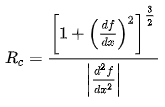

fuente:

Soto, J. (n.d.). *El radio de curvatura de johann bernoulli*. pimedios. Retrieved November 18, 2021, from http://pimedios.jesussoto.es/2016/11/02/el-radio-       

    de-curvatura-de-johann-bernoulli/. masaVehiculo=728; %kg

## **Cuarta Parte: determinación de valor máximo de velocidad con peralte**

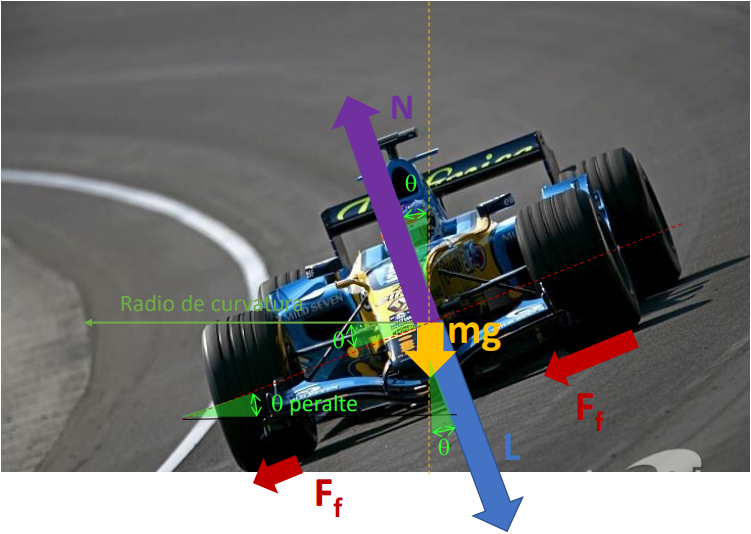

Respecto a la discusión que tuvimos sobre las fuerzas llegamos a las siguientes conclusiones:

Trabajo conservativo: Fuerza centrípeta

Trabajo no conservativo: fricción, L (downforce)

No realizan trabajo: Normal y mg 


Segmentos de Pista:
	1. Europa 1
	2. Europa 2
	3. Bélgica 1
	4. Bélgica 2
	5. Italia 1
	6. Italia 2
	7. Salir


menu = 4

f(x)=0.000030x^3 -0.107536x^2 127.096000x -49226.746938

f'(x)=(3 0.000030 x^2 -0.107536 x 127.096000) (x-x_n)+y_n

P(inicial)=(1082.206580 ,416.233300) m   P(final)=(1290.323230,208.116650) m

Demostración que los puntos evaluados en la función son iguales:


P(inicial)=(1082.206580 ,416.233300) m   P(final)=(1290.323230,208.116650) m


Max : (1082.21,416.23) m 

Min: (1290.32,208.12) m

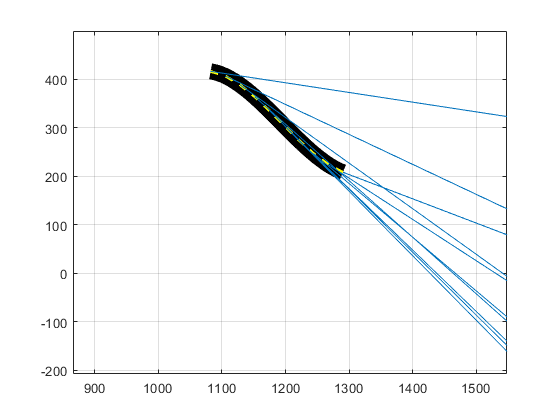

Puntos con radio de curvatura menor a 100

///////////////

(1082.206580,416.233300)=52.554214 m
(1083.206580,416.023240)=53.674224 m
(1084.206580,415.793178)=54.873308 m
(1085.206580,415.543296)=56.152668 m
(1086.206580,415.273773)=57.513581 m
(1087.206580,414.984789)=58.957403 m
(1088.206580,414.676525)=60.485561 m
(1089.206580,414.349161)=62.099556 m
(1090.206580,414.002876)=63.800956 m
(1091.206580,413.637850)=65.591401 m
(1092.206580,413.254265)=67.472598 m
(1093.206580,412.852299)=69.446321 m
(1094.206580,412.432134)=71.514410 m
(1095.206580,411.993948)=73.678773 m
(1096.206580,411.537923)=75.941385 m
(1097.206580,411.064237)=78.304288 m
(1098.206580,410.573072)=80.769592 m
(1099.206580,410.064608)=83.339478 m
(1100.206580,409.539024)=86.016199 m
(1101.206580,408.996500)=88.802078 m
(1102.206580,408.437217)=91.699518 m
(1103.206580,407.861355)=94.710998 m
(1104.206580,407.269094)=97.839081 m
(1284.206580,211.491695)=98.240416 m
(1285.206580,210.897386)=95.097500 m
(1286.206580,210.319454)=92.071514 m
(1287.206580,209.758078)=89.159886 m
(

Longitud de Curva: 298.248136 m

La velocidad máxima en el punto (1082.21,416.23) en la curva con peralte de 15.00 grados es 26.30 m/s
La velocidad máxima en el punto (1105.33,406.58) en la curva con peralte de 15.00 grados es 38.35 m/s
La velocidad máxima en el punto (1128.45,388.37) en la curva con peralte de 15.00 grados es 64.61 m/s
La velocidad máxima en el punto (1151.58,363.82) en la curva con peralte de 15.00 grados es 171.44 m/s


En el punto (1174.70,335.16) en la curva con peralte de 15.00 grados es una linea recta, no hay un limite de velocidad
En el punto (1197.83,304.61) en la curva con peralte de 15.00 grados es una linea recta, no hay un limite de velocidad
En el punto (1220.95,274.41) en la curva con peralte de 15.00 grados es una linea recta, no hay un limite de velocidad


La velocidad máxima en el punto (1244.08,246.77) en la curva con peralte de 15.00 grados es 110.06 m/s
La velocidad máxima en el punto (1267.20,223.93) en la curva con peralte de 15.00 grados es 54.16 m/s
La velocidad máxima en el punto (1290.32,208.12) en la curva con peralte de 15.00 grados es 33.51 m/s



Segmentos de Pista:
	1. Europa 1
	2. Europa 2
	3. Bélgica 1
	4. Bélgica 2
	5. Italia 1
	6. Italia 2
	7. Salir


menu = 7

%Valores usados en los cálculos:
theta=15; %grados
coeficienteDrag=1; %sin unidades
coeficcienteLift=2.01; %sin unidades
coeficienteFriccion=1.6; %sin unidades
areaFrontal= 1.1; %m^2 
masaVehiculo=728; %kg
Lmax=37155; %N, No usado pero se pasa de la presentación para uso posible en el futuro
DensidadAire=1.225; %kg/m^3
constanteGravedad=9.81; %m/s/s
radioCurvatura=((1+dy_p(misPuntos).^2).^(3/2))./dy_p_2(misPuntos); %derivado de la investigación
fprintf('Puntos con radio de curvatura menor a 100')
fprintf('///////////////')
for i=xmin:1:xmax
    rc=abs(((1+dy_p(i)^2)^(3/2))/dy_p_2(i));
    if rc<100
        fprintf("(%f,%f)=%f m\n",i,y_p(i),rc)
    end
end
lc = @(x) sqrt(1+(3*C3*x.^2+2*C2*x+C1).^2);
inte=integral(lc,xmin,xmax);    
    fprintf("Longitud de Curva: %f m",inte)
%Este for funciona para cualquier ángulo, incluyendo a una pista plana con teta=0, 
% usa el linspace generado anteriormente.
for i=1:10 
%     x=((masaVehiculo/abs(radioCurvatura(1,i))))
%     y=(cosd(theta)*coeficcienteLift*DensidadAire*areaFrontal*coeficienteFriccion/2)
%     z=y-x
%   velocidadMax= sqrt(abs((masaVehiculo*constanteGravedad*(coeficienteFriccion*cosd(theta)+sind(theta)))/((masaVehiculo/(radioCurvatura(1,i)))-(cosd(theta)*coeficcienteLift*DensidadAire*areaFrontal*coeficienteFriccion/2))));
    a=(1/2)*DensidadAire*coeficcienteLift*areaFrontal;
    velocidadCuadrada=(masaVehiculo*constanteGravedad)/((masaVehiculo/abs(radioCurvatura(1,i))+a*sind(theta))*(-coeficienteFriccion*sind(theta)+cosd(theta)/coeficienteFriccion*cosd(theta)+sin(theta))-a*cosd(theta));
    if velocidadCuadrada<0
        velocidadMax=88.8889; %%Velocidad maxima del auto
        fprintf("En el punto (%.2f,%.2f) en la curva con peralte de %.2f grados es una linea recta, no hay un limite de velocidad\n", misPuntos(1,i),misYs(1,i),theta)
    else
        velocidadMax=sqrt(velocidadCuadrada);
        fprintf("La velocidad máxima en el punto (%.2f,%.2f) en la curva con peralte de %.2f grados es %.2f m/s\n", misPuntos(1,i),misYs(1,i),theta,velocidadMax)
    end
    end
    end

end

**Fuentes para constantes:**

Hall, N. (2021, May 13). *The Lift Equation*. NASA GLENN RESEARCH CENTER. Retrieved November 19, 2021, from [https://www.grc.nasa.gov/WWW/K-12/airplane/lifteq.html](https://www.grc.nasa.gov/WWW/K-12/airplane/lifteq.html)

H.K.T. (2021, November 20). *Mercedes can’t abandon the current rear wing design is really helpless*. MIN NEWS. Retrieved November  19, 2021, from [https://min.news/en/sport/582ecf4b3dc710a60049f3f5c1d6443d.html](https://min.news/en/sport/582ecf4b3dc710a60049f3f5c1d6443d.html)

Toet, W. (2016). *Aerodynamics of f1*. Formula 1 Dictionary. Retrieved November 19, 2021, from  [http://www.formula1-                 dictionary.net/aerodynamics_of_f1.html#:~:text=Due%20to%20the%20nature%20of%20the%20vehicles%2C%20the,as%20much%20as%20a%20good%20modern%20road%20car.](http://www.formula1-dictionary.net/aerodynamics_of_f1.html#:~:text=Due%20to%20the%20nature%20of%20the%20vehicles%2C%20the,as%20much%20as%20a%20good%20modern%20road%20car.)